# Neurotech 2021 - Notebook 3: Reading Supplement

## Intro to Null Hypothesis Significance Testing with a Coin Example

**Sam Michalka - Olin College of Engineering**

## Commentary on this assignment

This notebook introduces null hypothesis significance testing (an aspect of Frequentist Statistics). There are myriad examples of where people use hypothesis testing (see most science articles), including comparing data to some particular value, comparing two groups, and testing if there is a consistent relationship between two variables. While it's not a common actual use case, here we will use a coin flipping example to help us consider the theory, building upon what we've already learned in the context of Bayes Theorem and conditional probabilties.

I strongly suggest you read both:

[Reading 17a in the "textbook" by J. Orloff and J. Bloom](https://drive.google.com/file/d/1vYWcrqcCx2Ky0bvFSPAwM2w08UljxMIA/view?usp=sharing)

[Reading 17b in the "textbook" by J. Orloff and J. Bloom](https://drive.google.com/file/d/1k6cFk6xKiJvPNnH4qQ-DPIrEwg-Cr7xe/view?usp=sharing)

This notebook is intended to highlight some of the key ideas from the reading assignment and demonstrate them using Matlab.

As with previous assignments, you might opt to start by reading first, or you might hop into the guided code and exercises below and consult the reading or other resources as helpful (in this case, you might still want to read 17a first as general framing). 

You may also find [these comprehension questions](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/reading-questions-17b/) helpful to check your understanding of the reading.

## Skills and topics

- Null hypothesis significance testing concepts

- Understanding p-values in relation to conditional probabilties

## Resources

Here are some other resources that might be helpful to support your understanding if this isn't working for you or if you just want more:

- [Guidelines for hypothesis testing data analysis](https://docs.google.com/document/d/1un3ktVI5TszrWPqvOtlkFC-b8ghoYDOqR86uorV5A_Y/edit?usp=sharing): this document outlines a general process to follow when approaching (inferential) statistical analysis.

- Intro to probability and statistics readings. I suggest you start with reading 17a/b, then 18 and 19 if you want to go deeper. There are also reading questions to check your understanding. [https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/) 

- [Overview of hypothesis testing in Matlab](https://www.mathworks.com/help/stats/hypothesis-testing.html) by Mathworks

- [Khan Academy explanation of hypothesis testing (and t-tests)](https://www.khanacademy.org/math/statistics-probability/significance-tests-confidence-intervals-two-samples/comparing-two-means/v/statistical-significance-experiment)

- [Statistics in Matlab textbook - see Chapter 5 on hypothesis testing (starts on pdf page 138)](https://drive.google.com/file/d/0B4-W3u6lQTCjZk1rdVZKVXZRYUk/view?usp=sharing)

- [Great explanation of hypothesis testing and tradeoff between Type I and Type II errors](http://www.cs.cmu.edu/~bhiksha/courses/10-601/hypothesistesting/hyptesting_outline.html)

- If you want to go pretty deep into a math/application paper about p-values and P(H|D), [this paper](https://www.frontiersin.org/articles/10.3389/fpsyg.2017.00908/full) dives in with some simulation. Not for the faint of heart (probably skip this unless you’re really into the math part of things)

## The Situation 

[Professor Alison Wood](https://www.olin.edu/faculty/profile/alison-wood/) has a lucky coin that she likes to use to make important decisions. Today, she's deciding if she's going to give you a copy of her album (oh yeah, Alison is a secret rockstar). 

First, you want to figure out if the coin is fair. In one scenario, you'll flip the coin ten times. In another scenario, you'll flip the coin 250 times (because you don't have anything better to do with your day). 

## Key terms and concepts in hypothesis testing

In our coin flip case, we're trying to determine if the data are different than what we would expect if the coin is fair. This is the comparison of some test statistic (number of heads) and some theorized distribution (probability of the number of heads if the coin is fair).

Let's introduce some terms:

**Null hypothesis (also H0 or **$H_0$** )**: This is the default assumption for the model generating the data. I like to think of this as "what the world looks like if nothing interesting is going on". You can think of this as a "cautious default".

**Alternative hypothesis (also HA or **$H_A$** ):** If we reject the null hypothesis, we accept this alternative as the best explanation of the data. The alternative hypothesis is often the composite of many possible alternatives and covers the rest of the options not covered by the null hypothesis.

**Test statistic (X): **We compute from the data. It might be a sum or a mean or something else depending on what we're trying to evaluate.

The general philosophy of null hypothesis significance testing is: We determine some null hypothesis. Then we determine if the test statistic summarizing our data is weird/surprising/unlikely compared to what we would expect to see if the null hypothesis is true. If our data's test statistic is weird/surprising/unlikely, then we reject the null hypotheis.

it's a bit easier to think through this with an example. For consistency with the reading, we'll let $\theta$ be the probability that the coin lands heads when flipped. For both of our scenarios (*theoretical 10 flips* and *many recorded flips*) the hypothesis are the same:

Null hypothesis: "the coin is fair" or $H_0 :\theta =0\ldotp 5$

Alternative hypothesis: "the coin is not fair" or $H_A :\theta \not= 0\ldotp 5$

In the *theoretical 10 flips scenario*, the test statistic is; X = number of heads in 10 flips.

Now we're going to generate **null distribution**. The null distribution is a probability function based on the null hypothesis.

In our case, we're dealing with discrete data representing the number of times one of two binary events happened (how many heads on multiple flips of a coin that can be heads or tails). As we explored in the first notebook, we'll use a binomial distribution. You initially explored binomial distributions using the disttool in Matlab. Here, we will transition to doing this with code.

This line makes a distribution object called mydist that has all kinds of useful pieces. The binomial distribution requires two pieces of information: how many total events (N) and the probability of a "success" (p), which in our case is the probability of heads (called theta above).

mydist = makedist('Binomial',"N",10,"p",0.5); 
format shortG; %This just makes the number formats consistent for easier viewing

Once we have this distribution object, we can use it to generate our null distribution.

The null distribution is the probability of each possible value of x given the state of the world set in our null hypothesis. This can be denoted as:


$$p\left(x\left|\theta =0\ldotp 5\right.\right)$$


In our *theoretical 10 flips scenario, *this null distribution is determined as a binomial distribution with 10 events and a probability of 0.5.

x = 0:10; % All the possible values of X
prob_x_given_H0  = mydist.pdf(x); %This outputs the probability of each of these values of x for this 
xprobtable = table([x;prob_x_given_H0],'RowNames',{'x';'P(x|H0)'},'VariableNames',{'values'})

xprobtable = 2×1 table
                  values    
               _____________

    x          [1×11 double]
    P(x|H0)    [1×11 double]


We can also plot this for easier visualization.

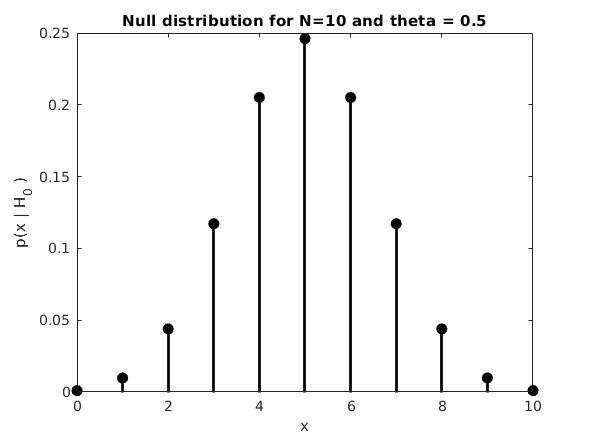

stem(x,prob_x_given_H0,'k','filled','LineWidth',2); ylabel('p(x | H_0 )'); xlabel('x'); title('Null distribution for N=10 and theta = 0.5')

## Critical values, alpha, and p-values

When we look at this null distribution, we see that we expect to get about 5 heads with 10 tosses of a fair coin. We will reject the null hypothesis (and it's corresponding null distribution), if we get data that are very weird/surprising/unlikely under this null hypothesis. But what does weird/surprising/unlikely mean?

Alas, we must choose that threshold based on our situation (and a bit of convention).

We can think about this in two ways:

- **Critical values:** What is the threshold value of x that is "too extreme"? Or what's the value of x for which we would choose to reject the null hypothesis

- **Alpha level (related to p-values):** If our null hypothesis is true, what is the probability that we will incorrectly reject this null hypothesis? (p-value) Or, what probability of being incorrect (when the null hypothesis is true) are we willing to accept? (alpha level, also called alpha value)

Let's first approach this from the perspective of cricitcal values. Looking at the stem plot, it appears that the values 0, 1, 2, 8, 9, and 10 are pretty unlikely if our null hypothesis is true. In our first look at this, let's reject the null hypothesis if the number of heads is any of these values.

We can see how probable each of the values are by looking at the table above.

We can also look up the probability of getting any particular value of x using the two vectors that we used to create the table (it's more intuitive to do this lookup with the vecors x and prob_x_given_H0. 

prob_x_given_H0(x==2)

ans =      0.043945


prob_x_given_H0(x > 7) % Probabilities for 8 9 and 10

ans =      0.043945    0.0097656   0.00097656


We'll can show the "rejection region" in red in our stem plot.

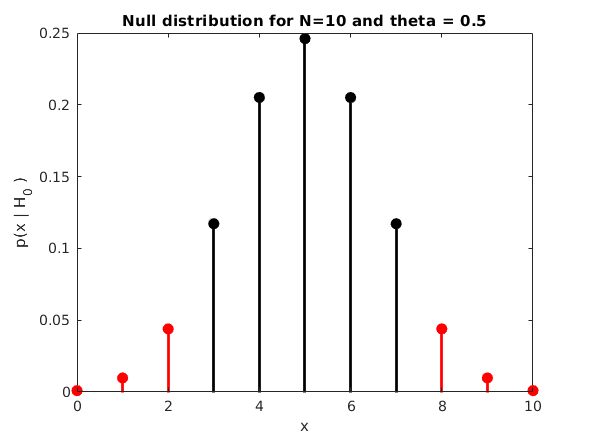

rejectionidx = (x < 3) | (x > 7); %This gives us the index of values of x that are less than 3 or more than 7
stem(x,prob_x_given_H0,'k','filled','LineWidth',2); ylabel('p(x | H_0 )'); xlabel('x'); title('Null distribution for N=10 and theta = 0.5'); hold on;
stem(x(rejectionidx),prob_x_given_H0(rejectionidx),'r','filled','LineWidth',2); hold off; %This turns the rejection region red

#### Exercise 1: Find the probability of getting a number of heads that falls in the rejection region if the null hypothesis is true.

sum(prob_x_given_H0(rejectionidx))

ans =       0.10937


This numer tells us that IF THE NULL HYPOTHESIS IS TRUE and we reject it if we get a value below 3 or above 7, we'll be wrong to reject the null hypothesis about 11% of the time (if we ran an infinite number of tests). 

**Critical values: **These are the values that mark the start of the rejection region(s). In the example above, our critical values are 2 and 8. Anything that is 2 or "more extreme" (lower) and 8 or "more extreme" (higher) will incite us to reject the null hypothesis. 

In our first round of thinking about this, we started by selecting the critical values, and then finding the probability of rejecting $H_0 \;$when $H_0$ is true, or ${P\left(\textrm{reject}\;H_0 \;\left|\;H_0 \right.\right)=0\ldotp 109}$. 

Typically, we start from the second option mentioned, which is to select an alpha level (how often we are okay with being wrong about rejecting the null hypothesis when it's true). The process here is:

- Select an alpha level. Common values for an alpha level are 0.10, 0.05, 0.01. This choice depends on several factors, including the consequences of being wrong.

- Determine the critical values and rejection region(s). (The reading talks about one-sided and two-sided examples. We will only focus on two-sided, as these are more common.)

- Compare the test statistic of our data (# of heads) to the critical values to determine if it is in the rejection region.

- If it's in the rejection region, we "reject the null hypothesis". If it is not in the rejection region, then we "fail to reject the null hypothesis". (Note the important double negative here... we are not accepting the null... we're just saying that we don't have enough evidence to reject it.)

If we set the alpha value at 0.12, we will reject the null hypothesis for the values of 0, 1, 2, 8, 9, and 10. 

In order to find the critical values based on our alpha level, we can make use of something called the inverse cumulative distribution function. As you might recall, the cumulative distribution function gives the probabiltiy that the variable takes a value less than or equal to x. We can add the CDF to our table to make sure we understand this.

xprobtable = table([x;prob_x_given_H0; mydist.cdf(x)],'RowNames',{'x';'P(x|H0)';'CDF'},'VariableNames',{'values'})

xprobtable = 3×1 table
                  values    
               _____________

    x          [1×11 double]
    P(x|H0)    [1×11 double]
    CDF        [1×11 double]


Start by selcting an alpha level. We'll be using a two-sided critical region (since our coin can be biased for heads or tails), so we need to divide the alpha value by 2 to determine the critical value on the left side and then again on the right side. The figure below illustrates this for the continuous data version of this.

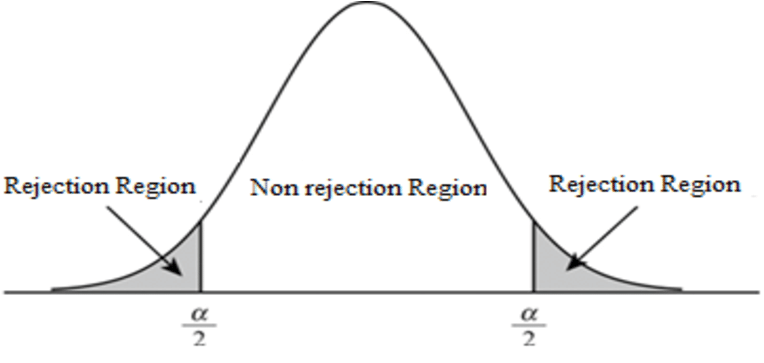

alpha = 0.12;
loweralpha = alpha./2; % Divide by 2 since this is two-sided
upperalpha = 1 - (alpha./2); % Same as lower alpha but subtract from 1

Then we can use the inverse cumulative distribution function to find the lowest and highest values of x that fall in our non-rejection region. The inverse cumulative distribution function (icdf) takes in a probability and outputs a value of x.

mydist.icdf(loweralpha)

ans =      3


mydist.icdf(upperalpha)

ans =      7


We find the rejection region in the same way we did before. We can spit out these values to confirm.

rejectionidx = (x < mydist.icdf(loweralpha)) | (x > mydist.icdf(upperalpha)); %This gives us the index of values of x that are less than 3 or more than 7
x(rejectionidx) % the values of x that are in our rejection region

ans =      0     1     2     8     9    10


And we can make a stem plot showing our rejection region in red.

stem(x,prob_x_given_H0,'k','filled','LineWidth',2); ylabel('p(x | H_0 )'); xlabel('x'); title('Null distribution for N=10 and theta = 0.5'); hold on;
stem(x(rejectionidx),prob_x_given_H0(rejectionidx),'r','filled','LineWidth',2); hold off; %This turns the rejection region red

#### Exercise 2: If we set $P\left(\textrm{reject}\;H_0 \;\left|\;H_0 \right.\right)=0\ldotp 05$, for which outcomes (#s of heads) will we reject the null hypothesis?

alpha2 = .05;
lower_alpha = alpha2./2;
upper_alpha = 1 - lower_alpha;

mydist.icdf(lower_alpha)

ans =      2


mydist.icdf(upper_alpha)

ans =      8



rejection2idx = (x < mydist.icdf(lower_alpha)) | (x > mydist.icdf(upper_alpha));
x(rejection2idx)

ans =      0     1     9    10


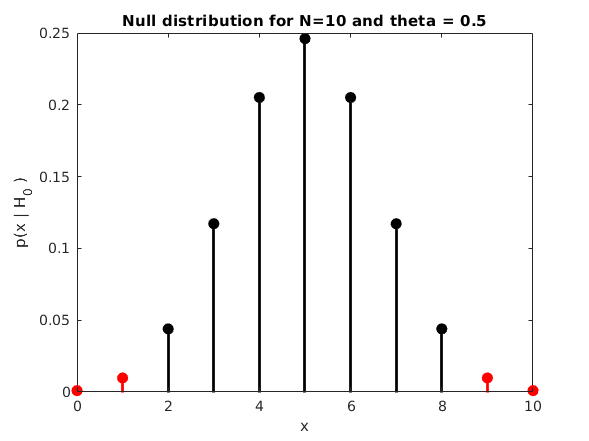


stem(x,prob_x_given_H0,'k','filled','LineWidth',2); ylabel('p(x | H_0 )'); xlabel('x'); title('Null distribution for N=10 and theta = 0.5'); hold on;
stem(x(rejection2idx),prob_x_given_H0(rejection2idx),'r','filled','LineWidth',2); hold off; %This turns the rejection region red

#### Exercise 3: What is the largest alpha level that would result in us never rejecting the null hypothesis in this situation?

%Prob of getting 0 or 10 heads
.00097656*2

ans =     0.0019531


Now we'll apply this to a situation where it's a bit tougher to just count... you instead flipped the coin 250 times and recorded the results (and then re-evaluated your life choices). If the coin were to be biased, you don't know in which direction (two-tailed).

#### Exercise 4: Plot the null hypothesis probability function for this new scenario. Describe what you observe.

clear
dist = makedist('Binomial',"N",250,"p",0.5); 
format shortG; %This just makes the number formats consistent for easier viewing

x = 0:250; % All the possible values of X
prob_x_given_H0  = dist.pdf(x); %This outputs the probability of each of these values of x for this 
xprobtable = table([x;prob_x_given_H0],'RowNames',{'x';'P(x|H0)'},'VariableNames',{'values'})

xprobtable = 2×1 table
                   values    
               ______________

    x          [1×251 double]
    P(x|H0)    [1×251 double]


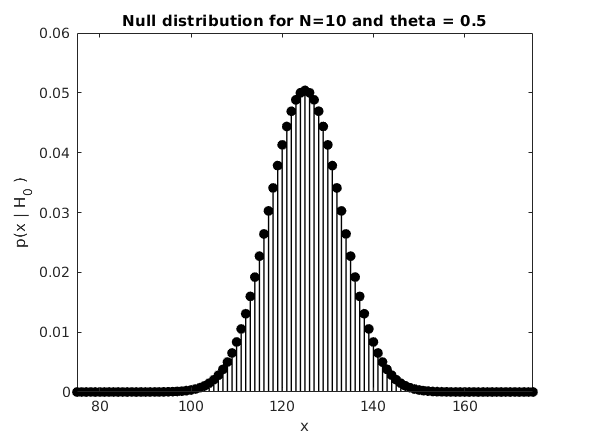


stem(x,prob_x_given_H0,'k','filled','LineWidth',1); ylabel('p(x | H_0 )'); xlabel('x'); title('Null distribution for N=10 and theta = 0.5')
xlim([75 175]);

This stem plot is a lot smoother than with fewer cion tosses because there is more data to plot. The max of P(x | H0) is also greater with 250 coin flips than with 10.

#### Exercise 5: What is the probability of getting exactly 125 heads?

p_125h = prob_x_given_H0(126)

p_125h =      0.050412


#### Exercise 6: What is the probability of getting fewer than 108 heads?

p_fewer_108h = sum(prob_x_given_H0(1,1:108))

#### Exercise 7: If you select an alpha level of 0.05. Will you reject the null hypothesis and tell Alison you think her coin is biased if you get exactly 100 heads?

alpha = .05

p_fewer_108h =      0.013329


lower_alpha = alpha./2;
upper_alpha = 1 - lower_alpha;


alpha =          0.05


dist.icdf(lower_alpha)
dist.icdf(upper_alpha)

rejectionidx = (x < dist.icdf(lower_alpha)) | (x > dist.icdf(upper_alpha));

ans =    110


x(rejectionidx)

ans =    140



%see rejection region
stem(x,prob_x_given_H0,'k','filled','LineWidth',2); ylabel('p(x | H_0 )'); xlabel('x'); title('Null distribution for N=250, theta = 0.5, alpha = .05'); hold on;

ans =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


stem(x(rejectionidx),prob_x_given_H0(rejectionidx),'r','filled','LineWidth',2); hold off; %This turns the rejection region red

rejectionidx(101) %yes, reject null hypothesis if exactly 100 heads

#### Exercise 8: What if you get 135 heads?

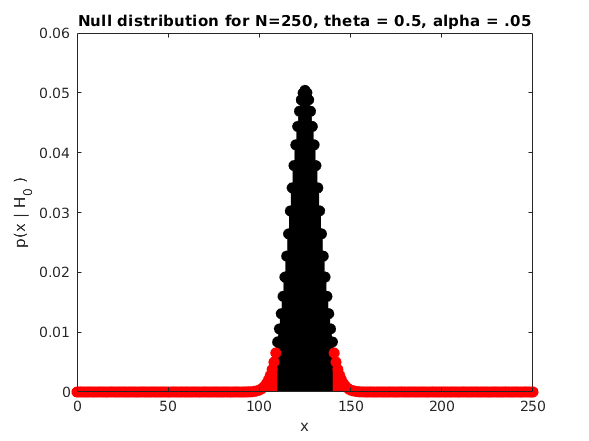

rejectionidx(135) %no, don't reject null hypothesis if 135 heads

#### Execise 9: What is the range of values for which you will "fail to reject the null hypothesis" if you are comfortable being wrong half of the time when the null is true or $P\left(\textrm{reject}\;H_0 \;\left|\;H_0 \right.\right)=0\ldotp 5$?

alpha = .5

ans = logical
   1


lower_alpha = alpha./2;
upper_alpha = 1 - lower_alpha;


ans = logical
   0


dist.icdf(lower_alpha);
dist.icdf(upper_alpha);


alpha =           0.5


rejectionidx = (x < dist.icdf(lower_alpha)) | (x > dist.icdf(upper_alpha));
x(rejectionidx)

%see rejection region
stem(x,prob_x_given_H0,'k','filled','LineWidth',2); ylabel('p(x | H_0 )'); xlabel('x'); title('Null distribution for N=250, theta = 0.5, alpha = .5'); hold on;
stem(x(rejectionidx),prob_x_given_H0(rejectionidx),'r','filled','LineWidth',2); hold off; %This turns the rejection region red

notrejectionidx = (x > dist.icdf(lower_alpha)) & (x < dist.icdf(upper_alpha));

ans =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


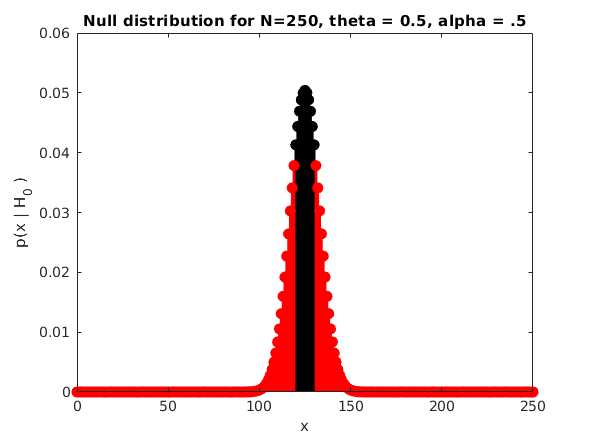

not_reject_range =    121   122   123   124   125   126   127   128   129


not_reject_range = x(notrejectionidx)